addpath("matlab_functions\")

global defect_count
defect_count = 0;
clear

#### Add defect to plate

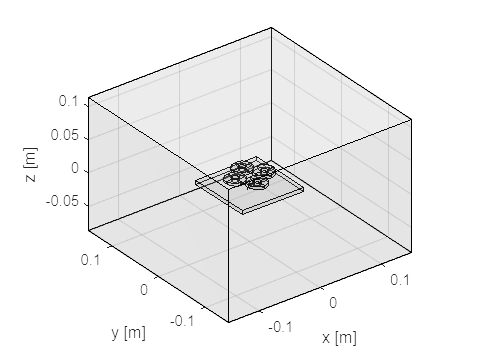

[model, Plate, Coil, Sensor] = myModel;
freqs = [900 225 100 55]; % (Hz)
mesh_size = 2; % 1:finest 9:coarsest

AddCuboidDefect  (model, 0,   0, 3e-3, 3e-3, 0, -2e-3)
AddCylinderDefect(model, 6e-3,0, 3e-3,       0, -3e-3)

figure
ComsolModel('PlotGeometry', model)

#### Compute fields

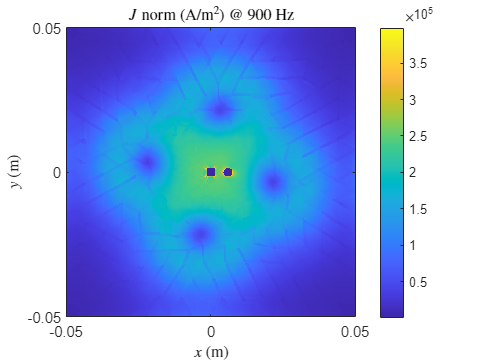

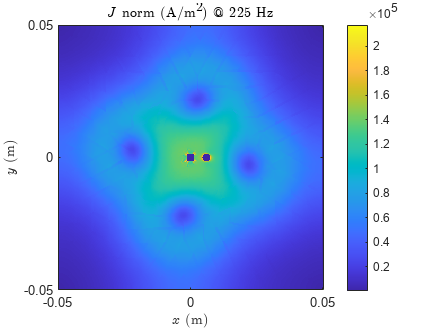

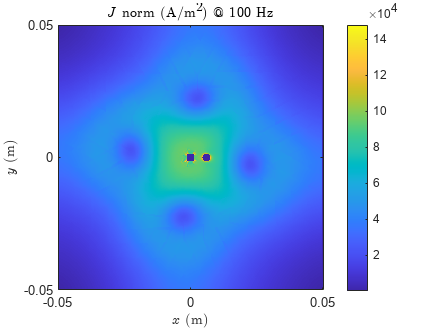

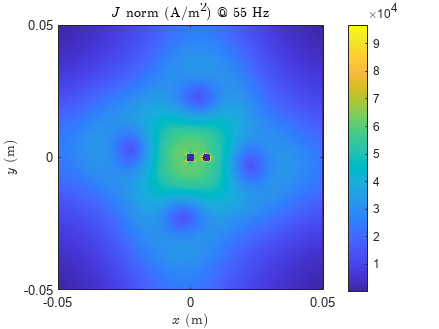

B_data = zeros(length(freqs), size(Sensor.positions,2));

for i = 1:length(freqs)
    model = ComsolModel('SolveCoil', model, Coil, freqs(i), mesh_size);
    
    [x,y,z] = ndgrid( ...
        linspace(-Plate.length/2, Plate.length/2, 500), ...
        linspace(-Plate.length/2, Plate.length/2, 500), ...
        -1e-3 );
    r = [reshape(x,1,[]); reshape(y,1,[]); reshape(z,1,[])];
    J = ComsolModel('InterpField', model, 'J', r);
    
    figure
    imagesc([-Plate.length/2 Plate.length/2],[-Plate.length/2 Plate.length/2], ...
            reshape(vecnorm(J),500,500).')
    colorbar
    axis square xy
    xlabel('$x$ (m)', 'Interpreter','latex')
    ylabel('$y$ (m)', 'Interpreter','latex')
    title(sprintf('$J$ norm (A/m$^2$) @ %d Hz',freqs(i)), 'Interpreter','latex')

    B = ComsolModel('InterpField', model, 'B', Sensor.positions);
    B_data(i,:) = dot(B, Sensor.axes);
end


clear i x y z r J B mesh_size

#### Export sensor data

fname = sprintf('data/B_%s.txt', datetime('now','Format','MMdd-HHmm'));
writematrix([freqs(:) B_data], fname)

clear fname

function AddCuboidDefect(model, x,y,dx,dy,z1,z2)

global defect_count
defect_tag = sprintf('defect%d',defect_count+1);

geom = model.component('mod1').geom('geom1');
defect = geom.create(defect_tag, 'Block');
defect.set('base', 'center');
defect.set('pos', [x y (z1+z2)/2]);
defect.set('size', [dx dy abs(z1-z2)]);

AddDefect(model, defect_tag)

end

function AddCylinderDefect(model, x,y,d,z1,z2)

global defect_count
defect_tag = sprintf('defect%d',defect_count+1);

geom = model.component('mod1').geom('geom1');
defect = geom.create(defect_tag, 'Cylinder');
defect.set('pos', [x y min(z1,z2)]);
defect.set('r', d/2);
defect.set('h', abs(z2-z1));

AddDefect(model, defect_tag)

end

function AddDefect(model, defect_tag)

global defect_count
defect_count = defect_count + 1;

if defect_count == 1
    plate_tag = 'plate';
else
    plate_tag = sprintf('dif%d', defect_count-1);
end

geom = model.component('mod1').geom('geom1');
dif = geom.create(sprintf('dif%d',defect_count), 'Difference');
dif.selection('input').set(plate_tag);
dif.selection('input2').set(defect_tag);

geom.run

end